# Hierarchical Unsupervised Generative Embedding

## Introduction

This toolbox implements Hierarchical Unsupervised Generative Embedding (HUGE) with variational Bayesian inversion. This demo script provides a quick-start guide to using the HUGE toolbox to stratify heterogeneous cohorts via generative embedding or perform empirical Bayesian analysis. For a more detailed documentation, see the HUGE manual. For more information on the theory behind HUGE, please consult *Yao et al. Variational Bayesian Inversion for Hierarchical Unsupervised Generative Embedding (HUGE). NeuroImage (2018)*, available at [https://doi.org/10.1016/j.neuroimage.2018.06.073](https://doi.org/10.1016/j.neuroimage.2018.06.073).

## Generating Synthetic Data

Before applying HUGE, we need some data. Here, we use a simulated dataset, which we generate using the toolbox itself. The dataset is based on a three-region bilinear DCM with 20 subjects divided into two groups of 10 subjects each.

First, we define the network structure of the DCM and generate the experimental stimuli.

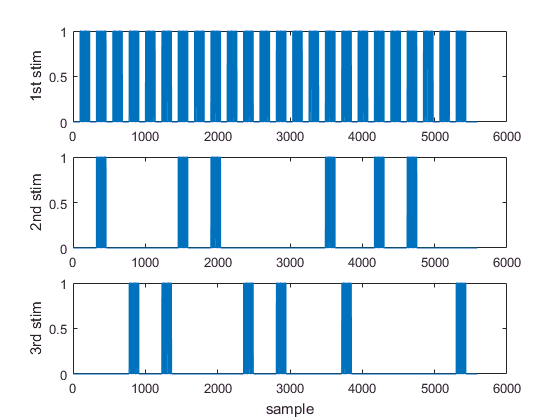

% fix random number generator seed for reproducible results
rng(8032, 'twister')

% define DCM network structure
dcm = struct( );
dcm.n = 3;
dcm.a = logical([ ...
    1 0 0; ...
    1 1 1; ...
    1 1 1; 
]);
dcm.c = false(dcm.n, 3);
dcm.c([1, 5]) = true;
dcm.b = false(dcm.n, dcm.n, 3);
dcm.b(:, :, 3) = logical([ ...
    0 0 0; ...
    1 0 1; ...
    1 1 0; ...
]);
dcm.d = false(dcm.n, dcm.n, 0);


% generate experimental stimuli
U = struct();
U.dt = 1.84/16;
tmp = tapas_huge_boxcar(U.dt, [24*13 24], [2 26], [3/4 16/26], [0 0;0 0]);
nSmp = length(tmp{1}) + 160;
tmp{1}(nSmp) = 0;
tmp{2}(nSmp) = 0;
tmp{2} = tmp{1}.*tmp{2};
tmp{3} = zeros(1, 24);
tmp{3}([2 3 1 4 3 1] + (0:5)*4) = 1;
tmp{3} = reshape(repmat(tmp{3}, round(26/U.dt), 1), [], 1);
tmp{3}(nSmp) = 0;
tmp{3} = tmp{3}.*tmp{2};
tmp{4} = zeros(1, 24);
tmp{4}([4 2 3 1 1 4] + (0:5)*4) = 1;
tmp{4} = reshape(repmat(tmp{4}, round(26/U.dt), 1), [], 1);
tmp{4}(nSmp) = 0;
tmp{4} = tmp{4}.*tmp{2};
tmp = tmp(2:4);

U.u = circshift(cell2mat(tmp), 6*16, 1);
U.name = {'1st stim', '2nd stim', '3rd stim'};
dcm.U = U;
dcm.Y.dt = 16*dcm.U.dt;
dcm.Y.name = {'1st reg'; '2nd reg'; '3rd reg'};
dcm.TE = .03;

% plot stimuli
figure;
for ip = 1:3
    subplot(3, 1, ip);
    plot(U.u(:, ip));
    ylabel(U.name{ip})
end
xlabel('sample')

Now, we specify two subgroups within our simulated cohort, which differ in their effective connectivity profile. The first group prefers a bottom-up configuration (1st region -> 2nd region -> 3rd region) while the second group prefers a top-down configuration (1st region -> 3rd region -> 2nd region).

sigma = .141; % group standard deviation
listGroups = cell(2, 1);

% group 1 (bottom-up)
dcm.Ep.A = [-.1  .0  .0; ...
             .2 -.1  .0; ...
             .0  .1 -.1;];
dcm.Ep.B = zeros(dcm.n, dcm.n, 3);
dcm.Ep.B(2, 1, 3) = .2;
dcm.Ep.B(3, 2, 3) = .35;
dcm.Ep.C = double(dcm.c)*.5;
dcm.Ep.D = double(dcm.d);
dcm.Ep.transit = zeros(dcm.n,1);
dcm.Ep.decay = zeros(dcm.n,1);
dcm.Ep.epsilon = 0;
tmp = [dcm.a(:);dcm.b(:);dcm.c(:);dcm.d(:)];
dcm.Cp = diag([double(tmp).*sigma.^2; ones(2*dcm.n+1, 1)*exp(-6)]);
listGroups{1} = dcm;

% group 2 (top-down)
dcm.Ep.A = [-.1  .0   .0; ...
             .0 -.1   .1; ...
             .4 -.15 -.1;];
dcm.Ep.B = zeros(dcm.n, dcm.n, 3);
dcm.Ep.B(3, 1, 3) = .35;
dcm.Ep.B(2, 3, 3) = .35;
listGroups{2} = dcm;


If you are familiar with SPM, you may have noticed that the data format we use to specify our desired DCM network structure resembles the DCM structure used by SPM. The HUGE toolbox uses the DCM structure of SPM to import experimental data, export results or specify the network structure for simulating data.

The HUGE toolbox itself is implemented as a Matlab class. Hence, the first step to using HUGE is to create an instance of the class using the *tapas_HUGE* command:

hugeSim = tapas_Huge('Tag', 'simulated 3-region DCM');

The *tapas_HUGE* command takes optional parameters in the form of name-value pair arguments. In the above example, we added a tag to the newly created HUGE object, containing a short description of the object. To get a list of all available name-value pairs, type:

help tapas_huge_property_names

  List of name-value pair arguments accepted by tapas_Huge() and estimate()
  
  NAME:        Confounds
  VALUE:       double array
  DESCRIPTION: Specify confounds for group-level analysis (e.g. age or sex)
               as double array with one row per subject and one column per
               confound. Note: This property can only be used in
               combination with the Dcm property.
  
  NAME:        ConfoundsVariant
  VALUE:       'none' | 'global' | 'cluster' (default: 'global' if
               confounds specified, 'none' otherwise)
  DESCRIPTION: Determines how confounds enter model. 'none': Confounds are
               not used. 'global': Confounds enter global regression 
               (variant 1). 'cluster': Confounds enter cluster-specific 
               regression (variant 2).
  
  NAME:        Dcm
  VALUE:       cell array of DCM structs in SPM format
  DESCRIPTION: Specify DCM structure and BOLD time series 

Now, we are ready to generate the dataset by simulating fMRI time series for each subject. After simulation, the ground truth model parameters are stored in the class property *model*. The fMRI time series (simulated or experimental) are stored in the class property called *data* and can be exported to SPM's DCM format using the *export* function.

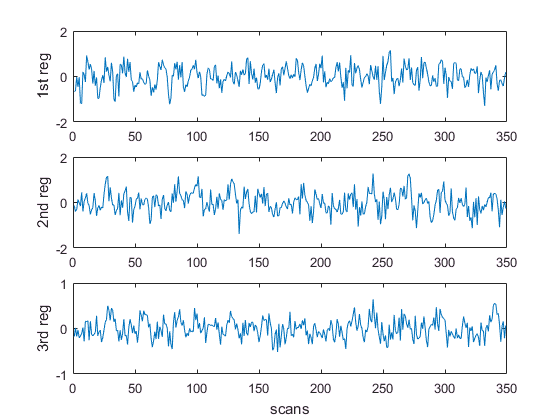

groupSizes = [10 10]; % simulate 10 subjects for each group
snr = .5; % using a signal-to-noise ratio of 0.5 (-3 dB)
hugeSim = hugeSim.simulate(listGroups, groupSizes, 'Snr', snr);

% plot simulated fMRI time series for one subject
n = 1;
figure;
for ip = 1:3
    subplot(3, 1, ip);
    plot(hugeSim.data(n).bold(:, ip));
    ylabel(hugeSim.labels.regions{ip})
end
xlabel('scans')


% export data to SPM's DCM format
[ listDcms ] = hugeSim.export();


## Stratification of Heterogeneous Cohorts

Using the simulated dataset from the previous section, we demonstrate how to stratify the cohort into the bottom-up and top-down subgroups. All we have to do is to call the method *estimate*.

% invert the HUGE model for the current dataset
% (this may take some time)
hugeSim = hugeSim.estimate('K', 2, 'Verbose', true);

Inverting HUGE with 2 clusters using VB.
iteration   1, dF: 3.80E+04.
iteration   2, dF: 1.09E+03.
iteration   3, dF: 5.65E+02.
iteration   4, dF: 7.85E+01.
iteration   5, dF: 4.74E+02.
iteration   6, dF: 3.31E+01.
iteration   7, dF: 7.07E+00.
iteration   8.
iteration   9, dF: 3.80E+00.
iteration  10, dF: 1.69E+00.
iteration  11, dF: 8.29E-01.
iteration  12, dF: 4.07E-01.
iteration  13, dF: 2.06E-01.
iteration  14, dF: 1.13E-01.
iteration  15, dF: 5.01E-02.
iteration  16, dF: 3.28E-02.
iteration  17, dF: 2.58E-02.
iteration  18, dF: 1.97E-02.
iteration  19, dF: 8.87E-03.
iteration  20, dF: 4.34E-03.
iteration  21, dF: 5.02E-03.
iteration  22, dF: 6.47E-03.
iteration  23, dF: 2.52E-03.
iteration  24, dF: 1.31E-03.
iteration  25, dF: 2.01E-03.
iteration  26, dF: 7.64E-04.
iteration  27, dF: 9.48E-04.
iteration  28, dF: 3.78E-04.
iteration  29, dF: 1.16E-03.
iteration  30, dF: 5.05E-04.
iteration  31, dF: 9.00E-04.
iteration  32, dF: 2.52E-04.
iteration  33, dF: 5.93E-05.
iteration  34, d

This method accepts the same name-value pair arguments as the *tapas_Huge* command we used to create the HUGE object in the last section. In the example above, we invert the HUGE model with two clusters and also activate command line outputs. The result is saved in the property *posterior* and can be plotted using the method *plot*. Since, we are using simulated data for which ground truth group assignments are available, the model will automatically calculate the balanced purity of the estimation result.

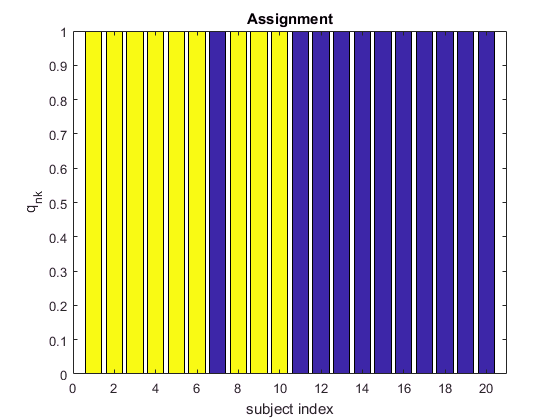

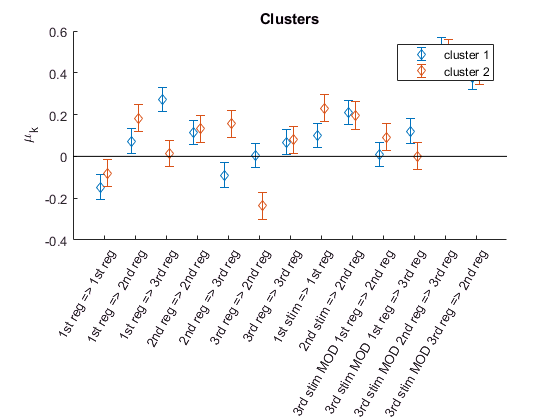

% plot result
plot(hugeSim)


% negative free energy
fprintf('Negative free energy: %e.\n', hugeSim.posterior.nfe)

Negative free energy: -3.638301e+03.



% balanced accuracy
fprintf('Balanced accuracy: %f.\n', hugeSim.posterior.bPurity)

Balanced accuracy: 0.950000.



% export result to SPM's DCM format
resultK2 = hugeSim.export();


Note how plotting the object generates two graphs. The first one shows the estimated group assignments for each subject. The second one shows the posterior estimates of the group-level DCM connectivity parameters for each group.

The negative free energy can be used to compare different models. For example, we can invert the HUGE model with three clusters, see how the negative free energy changes and calculate the Bayes factor between the two and three cluster models.

% invert the HUGE model with 3 clusters
% (this may take some time)
hugeSimK3 = hugeSim.estimate('K', 3);

Inverting HUGE with 3 clusters using VB.
iteration   1, dF: 3.80E+04.
iteration   2, dF: 1.09E+03.
iteration   3, dF: 5.65E+02.
iteration   4, dF: 7.85E+01.
iteration   5, dF: 4.74E+02.
iteration   6, dF: 3.31E+01.
iteration   7, dF: 7.07E+00.
iteration   8.
iteration   9, dF: 5.75E+00.
iteration  10, dF: 2.29E+00.
iteration  11, dF: 1.15E+00.
iteration  12, dF: 6.36E-01.
iteration  13, dF: 3.82E-01.
iteration  14, dF: 2.40E-01.
iteration  15, dF: 1.78E-01.
iteration  16, dF: 1.30E-01.
iteration  17, dF: 1.00E-01.
iteration  18, dF: 7.72E-02.
iteration  19, dF: 6.11E-02.
iteration  20, dF: 5.42E-02.
iteration  21, dF: 4.69E-02.
iteration  22, dF: 3.64E-02.
iteration  23, dF: 3.06E-02.
iteration  24, dF: 2.65E-02.
iteration  25, dF: 2.32E-02.
iteration  26, dF: 1.93E-02.
iteration  27, dF: 1.70E-02.
iteration  28, dF: 1.46E-02.
iteration  29, dF: 1.24E-02.
iteration  30, dF: 1.06E-02.
iteration  31, dF: 9.20E-03.
iteration  32, dF: 8.00E-03.
iteration  33, dF: 6.96E-03.
iteration  34, d


% compare negative free energy between 2 and 3 cluster models
fprintf('Difference in negative free energy: %f.\n', hugeSim.posterior.nfe - hugeSimK3.posterior.nfe)

Difference in negative free energy: 8.201616.



% calculate Bayes factor
BF_23 = exp(hugeSim.posterior.nfe - hugeSimK3.posterior.nfe);
fprintf('Bayes factor: %e.\n', BF_23)

Bayes factor: 3.646838e+03.


Note that options set via name-value pair arguments are persistent across the lifetime of the object. For example, the object remembers that the option *verbose* has been set to *true* in the previous section, and keeps generating command line outputs.

The difference in the negative free energy shows that the model prefers the two-cluster solution, which is what we would expect, given that the generating model contained two subgroups.

## Importing Data

In the previous example, we used the HUGE object itself to generate data. It is of course possible to import (experimental) fMRI time series into a HUGE object. The most convenient method is to use either the *tapas_Huge* or the *estimate* commands with the appropriate name-value pair argument.

% select the first 10 subjects (bottom-up group) from the previous example
listDcmsG1 = listDcms(1:10);

% create a new HUGE object and import the data from these subjects
hugeEb = tapas_Huge('Tag', 'Group 1 - bottom-up', 'Dcm', listDcmsG1);


Note that the data to be imported has to be stored in a cell array where each cell holds a DCM struct in SPM's DCM format. This allows for convenient transfer of data from SPM to HUGE.

## Empirical Bayes

Previously, we demonstrated how to use the HUGE toolbox to stratify a heterogeneous cohort. However, HUGE can also be used to perform empirical Bayesian analysis; i.e., to invert the DCMs while learning the prior over DCM parameters from the data. This is accomplished by setting the number of clusters to one.

% empirical Bayes
% (this may take some time)
hugeEb = hugeEb.estimate('K', 1, 'PriorClusterVariance', 0.02, 'Verbose', true);

Inverting HUGE with 1 cluster using VB.
iteration   1, dF: 2.02E+04.
iteration   2, dF: 1.48E+02.
iteration   3, dF: 8.45E+02.
iteration   4, dF: 9.03E+01.
iteration   5, dF: 1.45E+02.
iteration   6, dF: 8.64E+00.
iteration   7.
iteration   8, dF: 3.71E-01.
iteration   9, dF: 6.26E-02.
iteration  10, dF: 7.39E-02.
iteration  11, dF: 2.85E-02.
iteration  12, dF: 2.45E-03.
iteration  13, dF: 1.70E-05.
iteration  14, dF: 1.70E-04.
iteration  15, dF: 1.44E-06.
VB converged after 15 iterations. Negative free energy: -1.06E+03


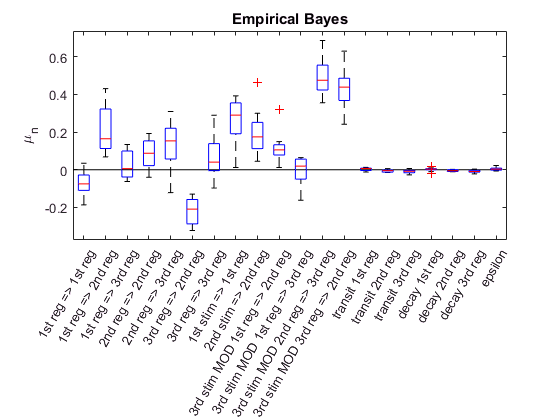

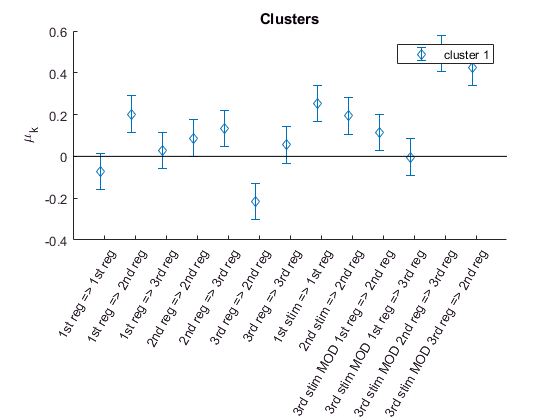


% plot result
plot(hugeEb);

Here, we also used a name-value pair argument to change the prior cluster variance. Note also that the *plot* method generates different graphs for empirical Bayesian analysis than for stratification. The first graph shows a boxplot of the posterior mean DCM parameter estimates of each individual subject. The second plot shows the population-level posterior mean and standard deviation.

In this case the second graph reveals that for example, the connection from the first to the second region in the current cohort is stronger than the standard prior value of zero.